clear; clc; close all;

%-------------------------------
% 参数设定（你可以自由修改）
%-------------------------------
D = 4000; % 需求规模
s = 2000;
alpha1 = 20;          % 效用参数 α1 > α2
beta = 10;
gamma = 35;
n = 6;
Cb = 20;
Cab = Cb/n; % 平均公交成本
Ct = beta*gamma/(beta+gamma)*D/s;        % 全私家车通勤成本
lambda = 4;        % 模块化公交效率参数
R_Nm_star = 5000;      % 固定收益（R(N_m^*)）
alpha2_max = alpha1*(1-Cab/Ct);
alpha2_SW = alpha1*(1-sqrt((Cab/(Ct^2))*(Cab-(lambda-1)/lambda*Ct)));
%-------------------------------
% 自变量：α2 的取值范围
%-------------------------------
alpha2 = linspace(0.1, alpha2_max, 400);  % 必须小于 alpha1


alpha2

alpha2 =     0.1000    0.1391    0.1783    0.2174    0.2565    0.2957    0.3348    0.3739    0.4131    0.4522    0.4913    0.5305    0.5696    0.6087    0.6479    0.6870    0.7261    0.7653    0.8044    0.8435    0.8827    0.9218    0.9609    1.0001    1.0392    1.0783    1.1175    1.1566    1.1957    1.2349    1.2740    1.3131    1.3523    1.3914    1.4305    1.4697    1.5088    1.5479    1.5871    1.6262    1.6653    1.7045    1.7436    1.7827    1.8219    1.8610    1.9001    1.9393    1.9784    2.0175



Nm = D/(2*n)*(1-alpha1 ./(alpha1-alpha2)*(Cab/Ct))

Nm =   261.5458  261.4044  261.2624  261.1198  260.9767  260.8330  260.6887  260.5438  260.3984  260.2524  260.1058  259.9586  259.8108  259.6625  259.5135  259.3639  259.2137  259.0629  258.9115  258.7595  258.6068  258.4535  258.2996  258.1451  257.9899  257.8341  257.6776  257.5205  257.3627  257.2043  257.0452  256.8854  256.7250  256.5639  256.4021  256.2396  256.0765  255.9126  255.7481  255.5828  255.4169  255.2502  255.0828  254.9148  254.7459  254.5764  254.4061  254.2351  254.0633  253.8908


p = 1/2*((alpha1-alpha2)/alpha1*Ct+Cab)

p =     9.4056    9.3903    9.3751    9.3599    9.3447    9.3295    9.3142    9.2990    9.2838    9.2686    9.2534    9.2382    9.2229    9.2077    9.1925    9.1773    9.1621    9.1468    9.1316    9.1164    9.1012    9.0860    9.0707    9.0555    9.0403    9.0251    9.0099    8.9947    8.9794    8.9642    8.9490    8.9338    8.9186    8.9033    8.8881    8.8729    8.8577    8.8425    8.8272    8.8120    8.7968    8.7816    8.7664    8.7512    8.7359    8.7207    8.7055    8.6903    8.6751    8.6598



Pi = n .*Nm .*p + R_Nm_star - Nm .*Cab

Pi = 1.0e+04 *

    1.8888    1.8857    1.8825    1.8794    1.8763    1.8731    1.8700    1.8668    1.8637    1.8606    1.8574    1.8543    1.8511    1.8480    1.8448    1.8417    1.8386    1.8354    1.8323    1.8291    1.8260    1.8228    1.8197    1.8165    1.8134    1.8102    1.8071    1.8039    1.8008    1.7976    1.7945    1.7913    1.7882    1.7850    1.7819    1.7787    1.7756    1.7724    1.7693    1.7661    1.7630    1.7598    1.7567    1.7535    1.7504    1.7472    1.7440    1.7409    1.7377    1.7346


CS = (lambda-1)/(2*lambda)*Ct*n .*Nm

CS = 1.0e+03 *

    9.1541    9.1492    9.1442    9.1392    9.1342    9.1292    9.1241    9.1190    9.1139    9.1088    9.1037    9.0986    9.0934    9.0882    9.0830    9.0777    9.0725    9.0672    9.0619    9.0566    9.0512    9.0459    9.0405    9.0351    9.0296    9.0242    9.0187    9.0132    9.0077    9.0021    8.9966    8.9910    8.9854    8.9797    8.9741    8.9684    8.9627    8.9569    8.9512    8.9454    8.9396    8.9338    8.9279    8.9220    8.9161    8.9102    8.9042    8.8982    8.8922    8.8862


SW = CS + Pi

SW = 1.0e+04 *

    2.8042    2.8006    2.7970    2.7933    2.7897    2.7860    2.7824    2.7787    2.7751    2.7714    2.7678    2.7641    2.7605    2.7568    2.7531    2.7495    2.7458    2.7421    2.7385    2.7348    2.7311    2.7274    2.7237    2.7200    2.7164    2.7127    2.7090    2.7053    2.7016    2.6979    2.6942    2.6904    2.6867    2.6830    2.6793    2.6756    2.6719    2.6681    2.6644    2.6607    2.6569    2.6532    2.6495    2.6457    2.6420    2.6382    2.6345    2.6307    2.6269    2.6232


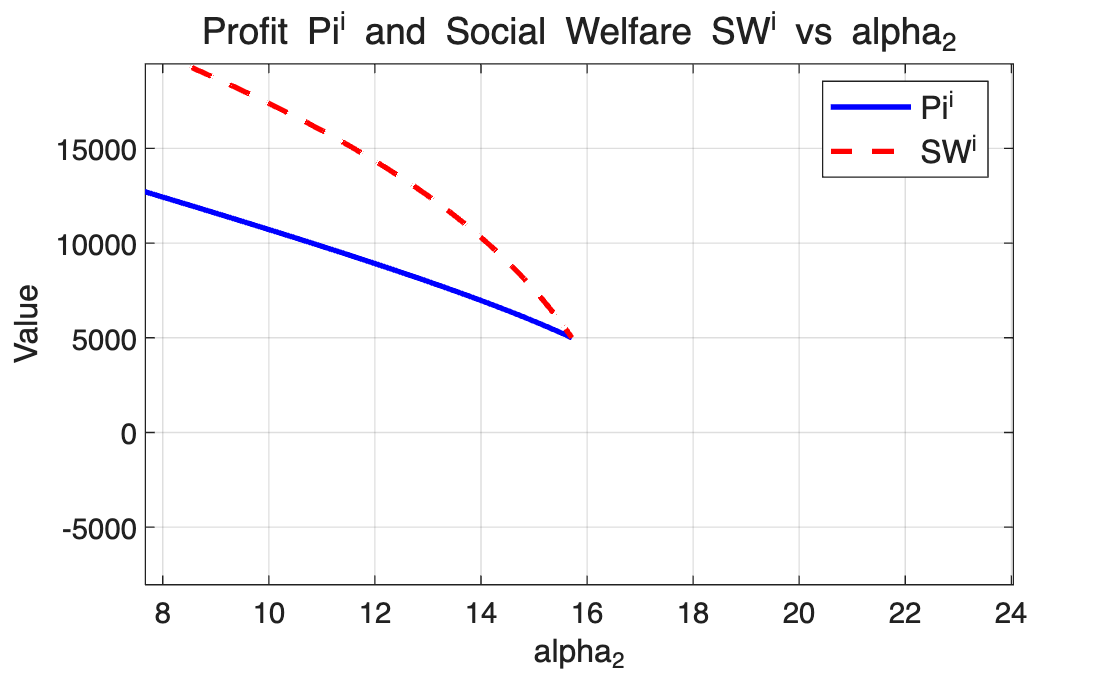



%-------------------------------
% 绘图
%-------------------------------
figure;
plot(alpha2, Pi, 'b-', 'LineWidth', 2); hold on;
plot(alpha2, SW, 'r--', 'LineWidth', 2);

xlabel('alpha_2', 'FontSize', 12);
ylabel('Value', 'FontSize', 12);
title('Profit Pi^i and Social Welfare SW^i vs alpha_2', 'FontSize', 14);
legend({'Pi^i', 'SW^i'}, 'FontSize', 12, 'Location', 'best');

grid on; box on;